# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

This is different from "exercise_VolforecastRV20220521.mlx" only with t distribution in GARCH estimation

clc,clear
addpath("data_Files/")
addpath("m_Files_ClusterPartition/")
addpath("m_Files_GARCHfamily/")
addpath("m_Files_Color/colormap/");

load("dax_rv.mat")
load("ftse_rv.mat")
load("nikkie_rv.mat")
load("sp_rv.mat")
dax=readtable("DAX daily.xlsx");
dax(:,3:end)=[];dax.Properties.VariableNames=["Date","Price"]

dax = 8443×2 table
       Date        Price 
    ___________    ______

    02-Jan-1989    1335.1
    03-Jan-1989    1362.3
    04-Jan-1989    1373.2
    05-Jan-1989    1376.6
    06-Jan-1989      1361
    09-Jan-1989    1372.4
    10-Jan-1989    1353.5
    11-Jan-1989    1354.4
    12-Jan-1989    1361.9
    13-Jan-1989      1358
    16-Jan-1989    1350.6
    17-Jan-1989    1344.1
    18-Jan-1989    1316.7
    19-Jan-1989    1340.1
    20-Jan-1989    1330.1
    23-Jan-1989    1318.3


ftse=readtable("FTSE daily.xlsx");
ftse(:,3:end)=[];ftse.Properties.VariableNames=["Date","Price"]

ftse = 8437×2 table
       Date        Price 
    ___________    ______

    03-Jan-1989    1783.2
    04-Jan-1989    1785.7
    05-Jan-1989    1801.9
    06-Jan-1989    1798.1
    09-Jan-1989    1826.5
    10-Jan-1989    1828.6
    11-Jan-1989      1833
    12-Jan-1989    1837.5
    13-Jan-1989    1853.5
    16-Jan-1989    1866.6
    17-Jan-1989    1868.9
    18-Jan-1989    1871.7
    19-Jan-1989    1911.5
    20-Jan-1989    1908.7
    23-Jan-1989    1917.6
    24-Jan-1989    1922.7


nikkie=readtable("NIKKIE daily.xlsx");
nikkie(:,3:end)=[];nikkie.Properties.VariableNames=["Date","Price"]

nikkie = 8198×2 table
       Date        Price
    ___________    _____

    04-Jan-1989    30166
    05-Jan-1989    30260
    06-Jan-1989    30226
    09-Jan-1989    30223
    10-Jan-1989    30683
    11-Jan-1989    31010
    12-Jan-1989    31141
    13-Jan-1989    31148
    17-Jan-1989    31299
    18-Jan-1989    31244
    19-Jan-1989    31367
    20-Jan-1989    31275
    23-Jan-1989    31199
    24-Jan-1989    31350
    25-Jan-1989    31567
    26-Jan-1989    31580


sp=readtable("S&P500 daily.xlsx");
sp(:,3:end)=[];sp.Properties.VariableNames=["Date","Price"]

sp = 8413×2 table
       Date        Price 
    ___________    ______

    03-Jan-1989    277.71
    04-Jan-1989    275.41
    05-Jan-1989    279.44
    06-Jan-1989    279.99
    09-Jan-1989    280.68
    10-Jan-1989    280.96
    11-Jan-1989    280.35
    12-Jan-1989    282.01
    13-Jan-1989    283.17
    16-Jan-1989    283.86
    17-Jan-1989    284.12
    18-Jan-1989    283.55
    19-Jan-1989    286.54
    20-Jan-1989    286.89
    23-Jan-1989    287.85
    24-Jan-1989    284.49


## SP 500

Timeline=sp.Date;
Time_outsample=sp_rv_table.date;
logret=[0;price2ret(sp.Price)];
rv=sp_rv_table.rv;
Index='sp';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'STUDENTST','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],10,[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','STUDENTST',estimation.other,0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              9.1041e-05    0.00013188
    CPGARCH            8.9585e-05    0.00012981
    GARCH Ite.         8.9585e-05    0.00012981
    EGARCH             8.2276e-05    0.00011839
    CPEGARCH           8.0204e-05    0.00011431
    CPEGARCH Ite.      8.0204e-05    0.00011431
    GJRGARCH           8.9902e-05    0.00012972
    CPGJRGARCH         8.8692e-05     0.0001289
    CPGJRGARCH Ite.    8.8692e-05     0.0001289
    RSGARCH            7.0715e-05    0.00010257


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH               0.27222       0.53954      0.21339
    CPGARCH             0.29381       0.55382      0.23817
    GARCH Ite.          0.29381       0.55382      0.23817
    EGARCH              0.30736       0.62896      0.19959
    CPEGARCH            0.35285       0.66361      0.23938
    CPEGARCH Ite.       0.35285       0.66361      0.23938
    GJRGARCH            0.28331       0.55346       0.2201
    CPGJRGARCH          0.29829       0.55941      0.24091
    CPGJRGARCH Ite.     0.29829       0.55941      0.24091
    RSGARCH             0.48252       0.99036      0.19836


## Figure of volatility persistence

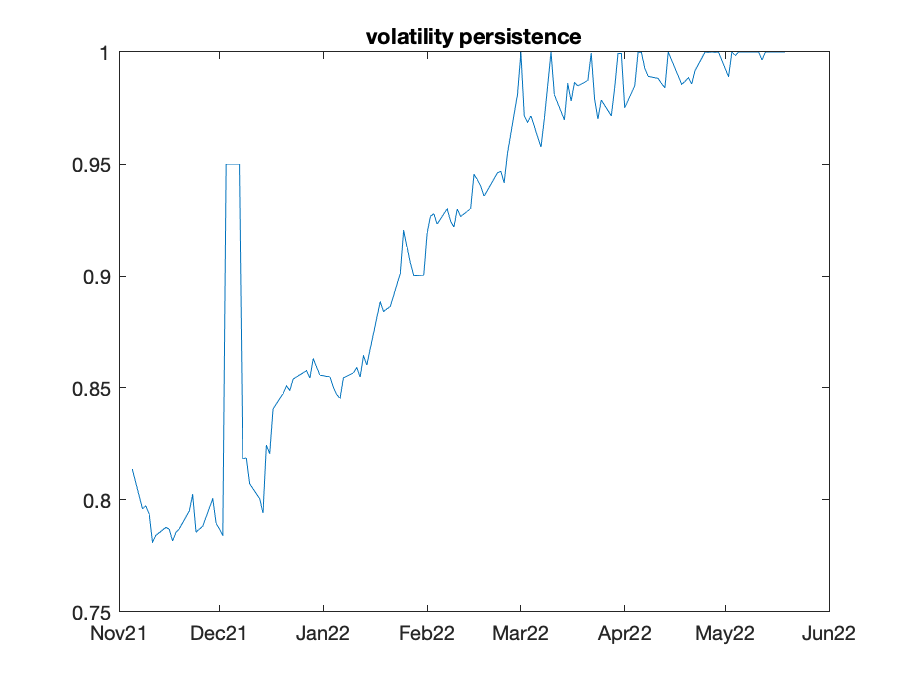

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_t_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## DAX 30

Timeline=dax.Date;
Time_outsample=dax_rv_table.date;
logret=[0;price2ret(dax.Price)];
rv=dax_rv_table.rv;
Index='dax';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'STUDENTST','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],10,[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','STUDENTST',estimation.other,0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

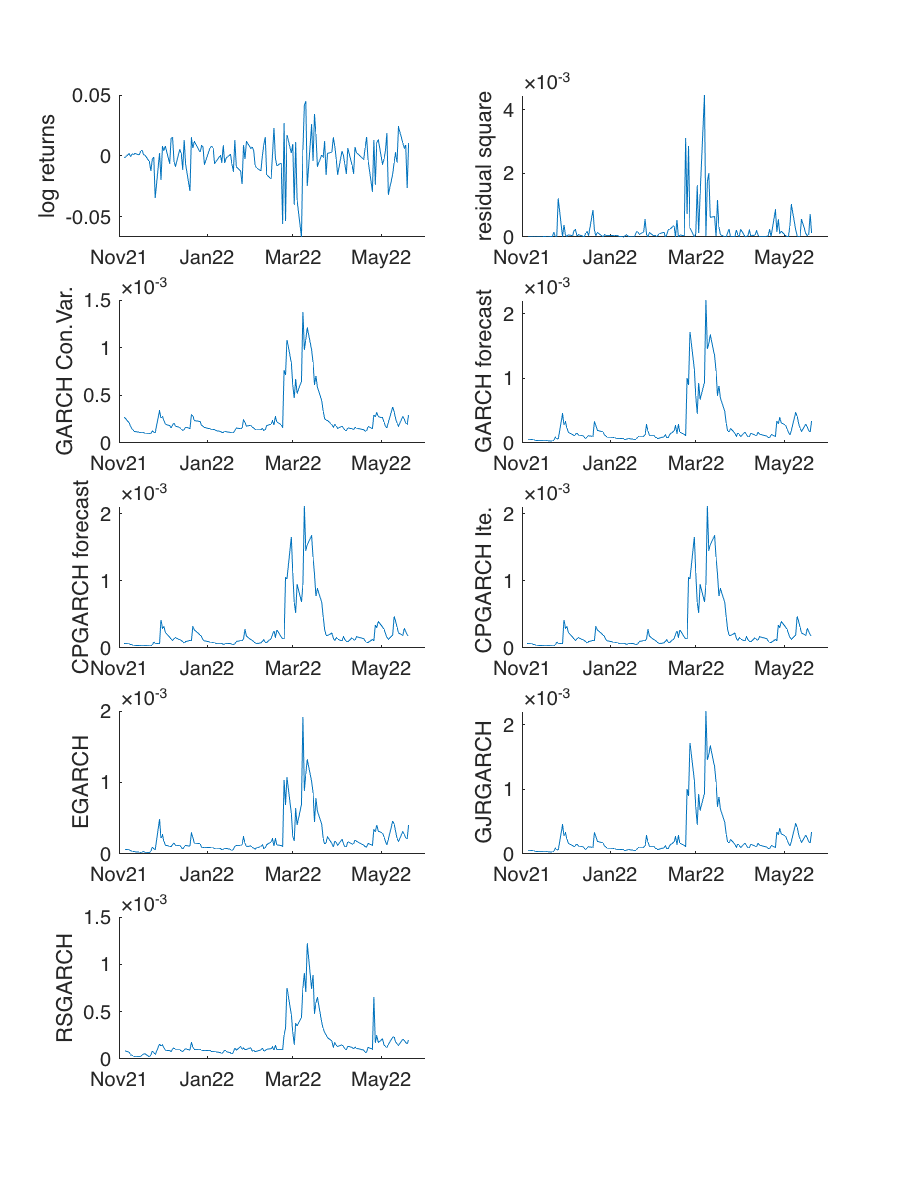

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

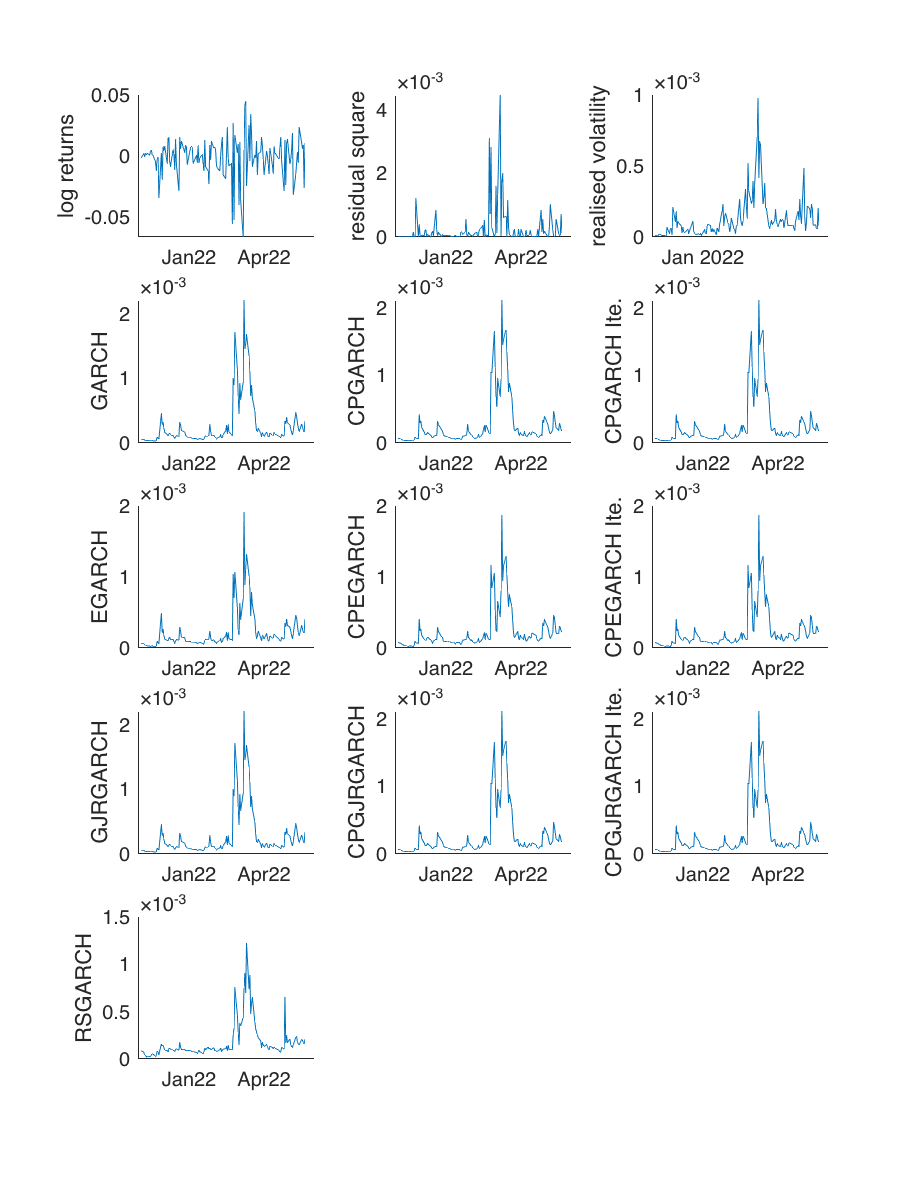

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

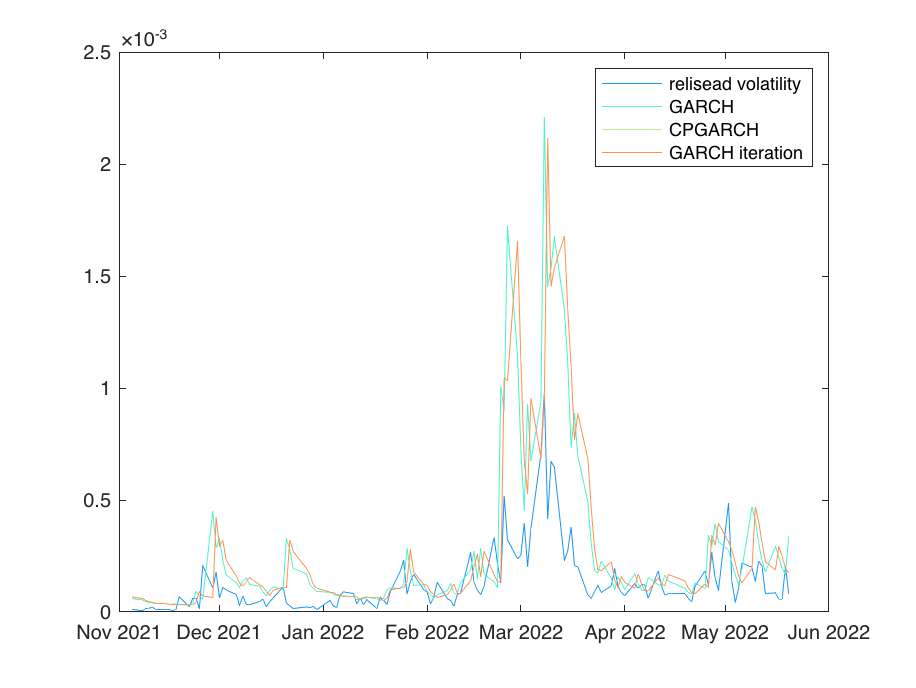

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

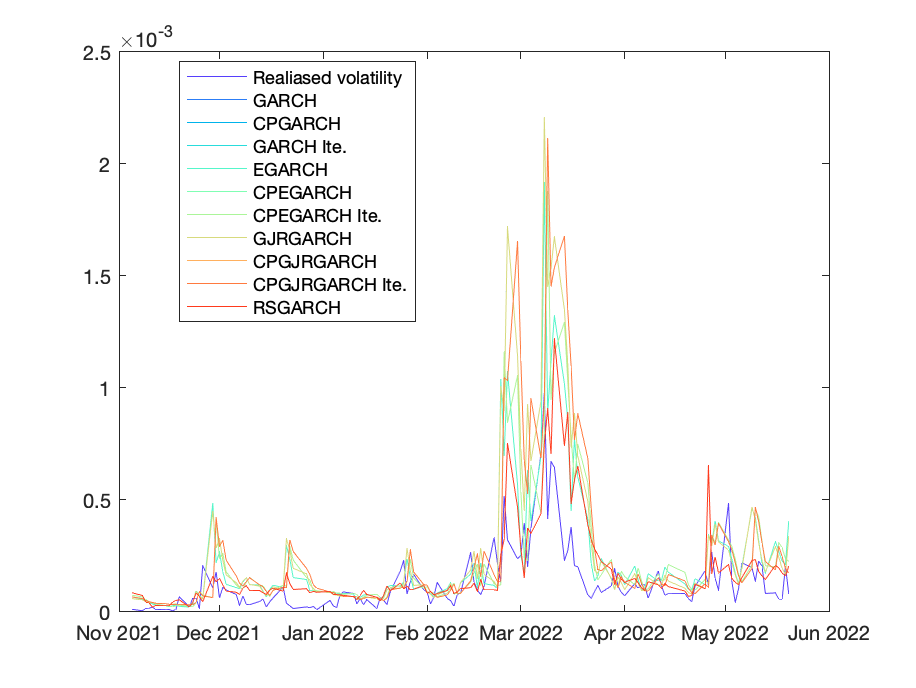

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00016707    0.00031249
    CPGARCH            0.00016562     0.0003279
    GARCH Ite.         0.00016562     0.0003279
    EGARCH             0.00012643    0.00021741
    CPEGARCH           0.00013254    0.00024117
    CPEGARCH Ite.      0.00013254    0.00024117
    GJRGARCH           0.00016707    0.00031249
    CPGJRGARCH         0.00016562     0.0003279
    CPGJRGARCH Ite.    0.00016562     0.0003279
    RSGARCH            9.2339e-05    0.00015179


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH               0.26488       0.34809      0.61127
    CPGARCH             0.21675       0.31604      0.45483
    GARCH Ite.          0.21675       0.31604      0.45483
    EGARCH              0.34824       0.46201      0.59506
    CPEGARCH            0.27569       0.40796      0.43631
    CPEGARCH Ite.       0.27569       0.40796      0.43631
    GJRGARCH            0.26489       0.34809      0.61127
    CPGJRGARCH          0.21675       0.31604      0.45483
    CPGJRGARCH Ite.     0.21675       0.31604      0.45483
    RSGARCH             0.42053       0.60861      0.46452


## Figure of volatility persistence

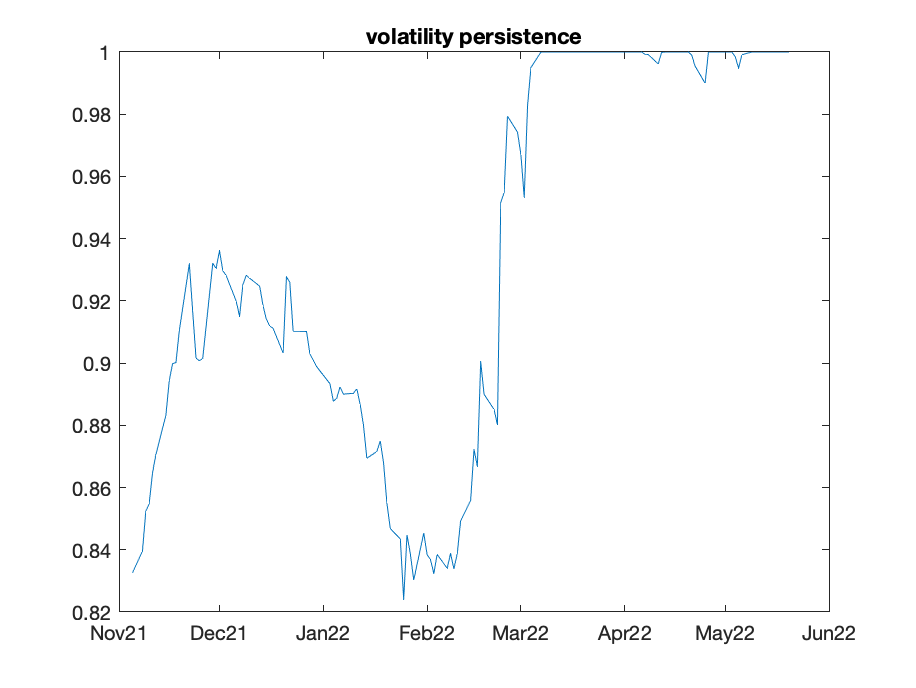

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_t_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## FTSE 200

Timeline=ftse.Date;
Time_outsample=ftse_rv_table.date;
logret=[0;price2ret(ftse.Price)];
rv=ftse_rv_table.rv;
Index='ftse';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'STUDENTST','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],10,[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','STUDENTST',estimation.other,0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

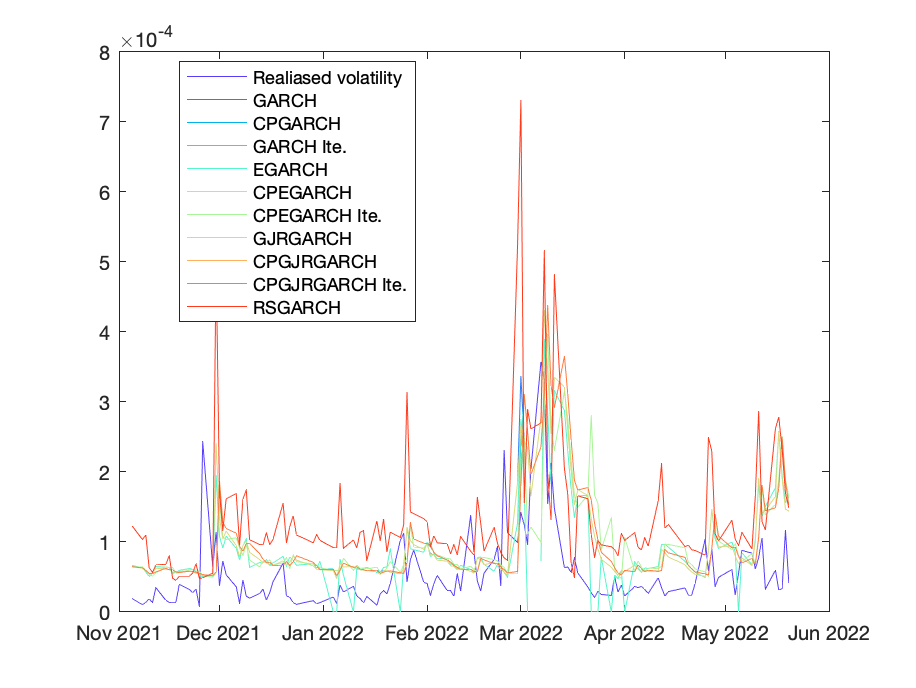

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              5.8026e-05    7.4854e-05
    CPGARCH            5.9909e-05    8.0387e-05
    GARCH Ite.         5.9909e-05    8.0387e-05
    EGARCH                    Inf           Inf
    CPEGARCH                  Inf           Inf
    CPEGARCH Ite.      5.9814e-05    7.9463e-05
    GJRGARCH           5.7477e-05    7.3727e-05
    CPGJRGARCH          5.948e-05    8.0043e-05
    CPGJRGARCH Ite.     5.948e-05    8.0043e-05
    RSGARCH             9.079e-05    0.00012028


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);

[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);

[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH               0.34902       0.56929       0.3383
    CPGARCH             0.26366       0.49617      0.23905
    GARCH Ite.          0.26366       0.49617      0.23905
    EGARCH                    0             0          NaN
    CPEGARCH                  0             0          NaN
    CPEGARCH Ite.       0.17687       0.46717      0.12648
    GJRGARCH            0.35724       0.58192       0.3395
    CPGJRGARCH          0.26183       0.49708      0.23439
    CPGJRGARCH Ite.     0.26183       0.49708      0.23439
    RSGARCH             0.16881       0.34323      0.20225


## Figure of volatility persistence

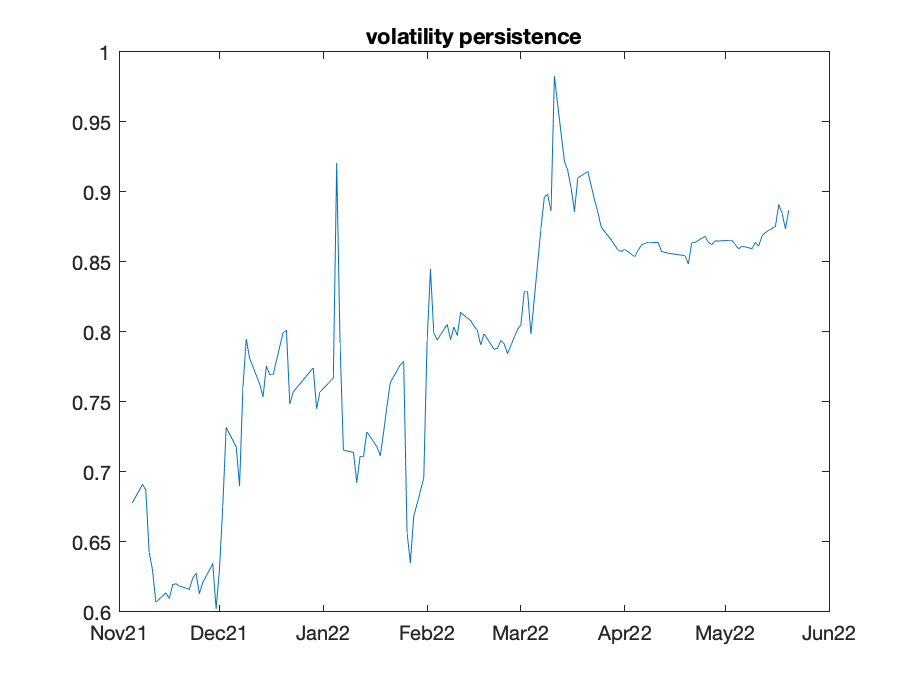

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_t_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## NIKKIE 225

Timeline=ftse.Date;
Time_outsample=ftse_rv_table.date;
logret=[0;price2ret(ftse.Price)];
rv=ftse_rv_table.rv;
Index='ftse';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,"Distribution","t");
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'STUDENTST','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],10,[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','STUDENTST',estimation.other,0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

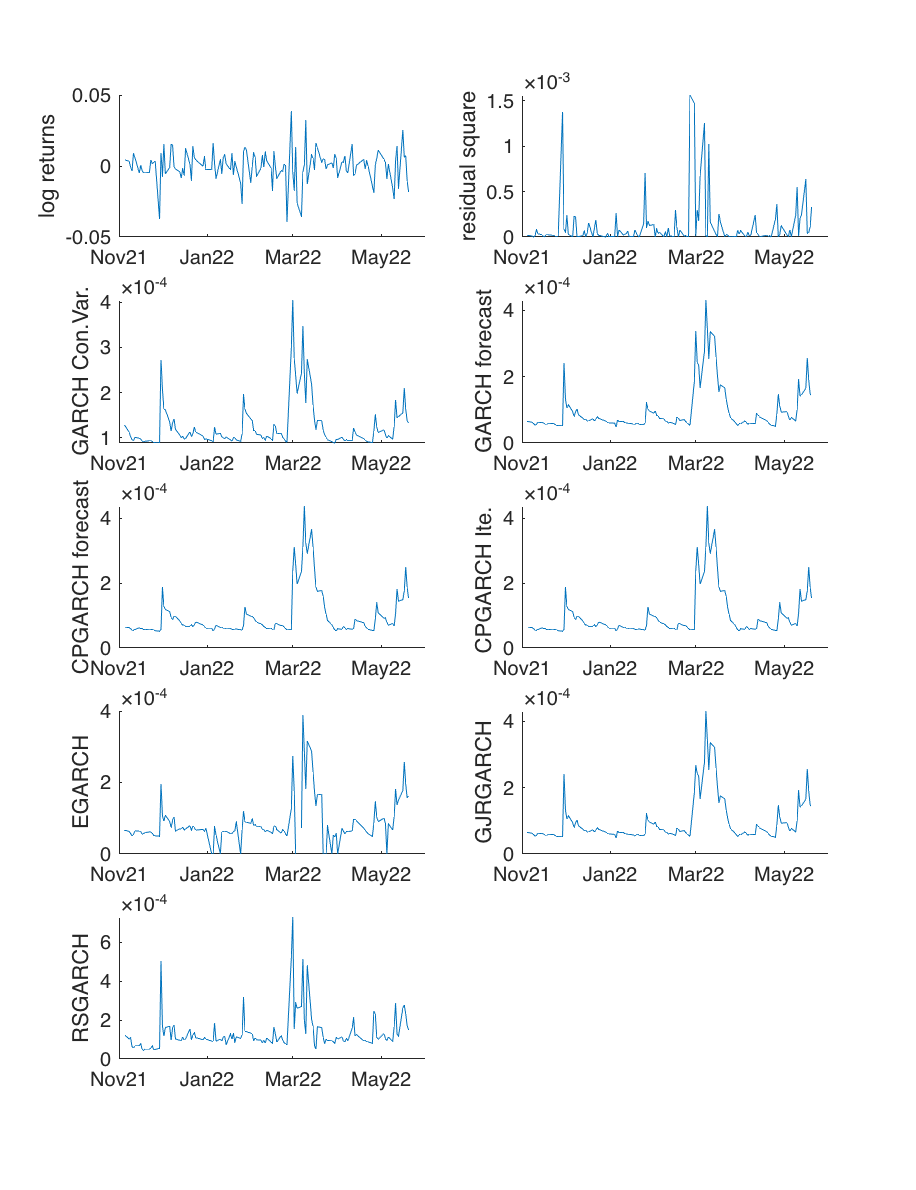

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

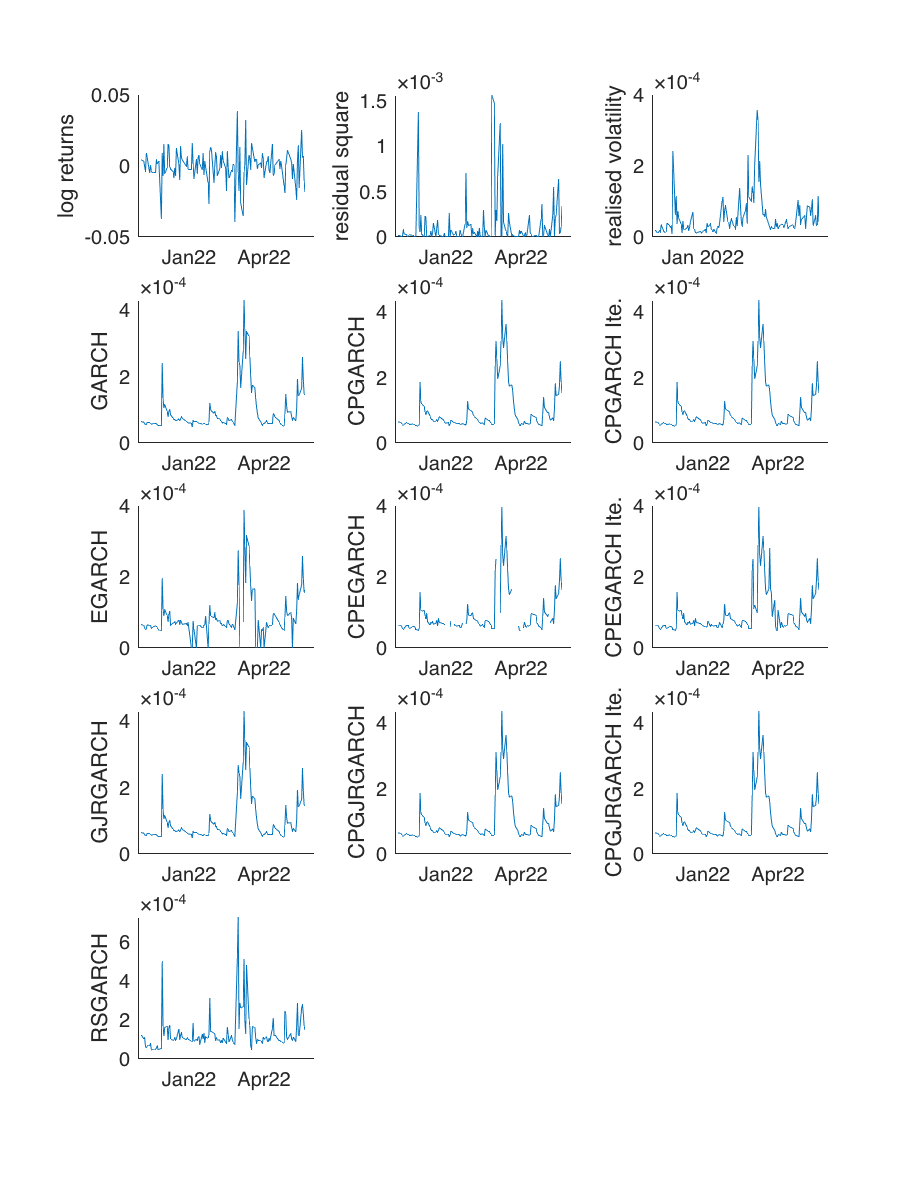

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

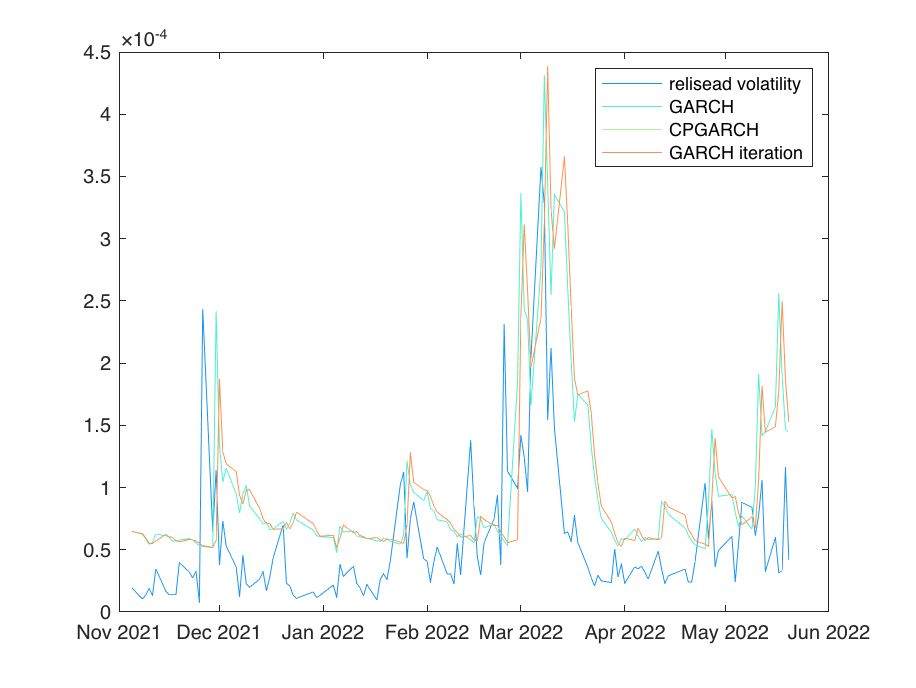

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              5.8026e-05    7.4854e-05
    CPGARCH            5.9909e-05    8.0387e-05
    GARCH Ite.         5.9909e-05    8.0387e-05
    EGARCH                    Inf           Inf
    CPEGARCH                  Inf           Inf
    CPEGARCH Ite.      5.9814e-05    7.9463e-05
    GJRGARCH           5.7477e-05    7.3727e-05
    CPGJRGARCH          5.948e-05    8.0043e-05
    CPGJRGARCH Ite.     5.948e-05    8.0043e-05
    RSGARCH             9.079e-05    0.00012028


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);

[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);

[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH               0.34902       0.56929       0.3383
    CPGARCH             0.26366       0.49617      0.23905
    GARCH Ite.          0.26366       0.49617      0.23905
    EGARCH                    0             0          NaN
    CPEGARCH                  0             0          NaN
    CPEGARCH Ite.       0.17687       0.46717      0.12648
    GJRGARCH            0.35724       0.58192       0.3395
    CPGJRGARCH          0.26183       0.49708      0.23439
    CPGJRGARCH Ite.     0.26183       0.49708      0.23439
    RSGARCH             0.16881       0.34323      0.20225


## Figure of volatility persistence

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_t_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");